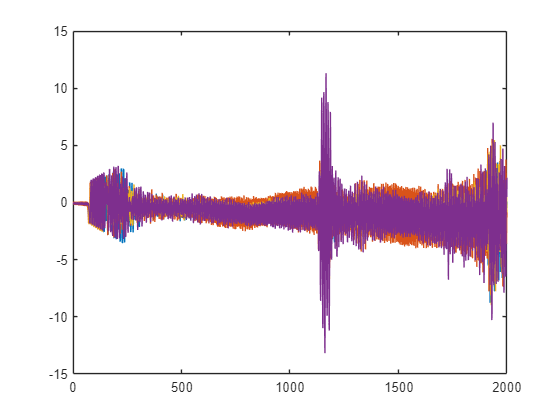

load test_data.mat -mat

%%test case%

c = 1136;           %speed of sound in air in ft/sec
SampleRate = 100000;
frequency = 10000;  % of pulse
samples_per_cycle = SampleRate / frequency;
N = 2000;           % number of samples taken per sensor; range = about 10 feet
NUpsampled = 2*N;   % number of samples after upsampling
FrameSize = N;
upsample = 2;       % later upsampling by 2
num_elements = 4;   % number of elements in array
cycles = 6;         % number of cycles in transmitted pulse
Fs_out = 44100;     % sample frequency of the output DAC
max_range = 100;    % range of the output display in # of pixels
min_range = 2;      % range blanked on the output display in # of pixels
pulse_length = cycles*samples_per_cycle; % pulse length in number of samples
top    = 0.9;     % top threshold for contrast enhancement (window/level) (must be between 0 and 1) 
bottom = 0.6;     % bottom thrseshold for contrast enhancement (window/level) (must be between 0 and 1)
colormap(gray);   % grayscale images, not color

% CREATE DATA ARRAYS NEEDED FOR FUNCTIONS
% NumBeams = 21; 
NumBeams = (samples_per_cycle*upsample) + 1;  %should be 21 for default case


data2 = zeros(N*upsample,num_elements); % preallocate and create zeros vector for upsampling (designed for upsample = 2)
beams = zeros(NumBeams, N*upsample);
demod_I = zeros(NumBeams, N*upsample+10);
demod_Q = zeros(NumBeams, N*upsample+10);
Mag_image = zeros(N*upsample, NumBeams);
persist_image = zeros(max_range,(2*max_range + 1));
SF = zeros(4,1);

% PRECOMPUTE LOOK-UP TABLES TO SPEED UP FUNCTIONS
% -- add your look-up tables here.  They don't cost you any time here


%time-gain computation 
sampleIndex = [1:1:2000;1:1:2000;1:1:2000;1:1:2000]';
timeGainValue = (1 + (sampleIndex.*c)/SampleRate);

plot(time_gain_compensation(data, timeGainValue))

iterations = 10

iterations =     10


sum = 0;

for i=1:iterations
    tic
    time_gain_compensation(data, timeGainValue);
    time = toc;
    sum = sum+time;
end
averageRuntime = sum/iterations

averageRuntime =      7.845000000000001e-05
